# Webcam Computer Vision Functions

Eliyahu Suskind and Mahderekal, 2/24/2023, Revision 1

clc       % clear command window
clear     % clear MATLAB workspace
imaqreset % clear images from memory

### Set Up Control System

% Detect and create webcam object
camList = webcamlist

camList = 2×1 cell array
    {'BisonCam, NB Pro'             }
    {'Microsoft® LifeCam Cinema(TM)'}


roboCam = webcam(2)

roboCam =   webcam with properties:

                     Name: 'Microsoft® LifeCam Cinema(TM)'
     AvailableResolutions: {'640x480'  '640x360'  '424x240'  '352x288'  '320x240'  '176x144'  '160x120'  '1280x720'  '960x544'  '800x448'  '800x600'}
               Resolution: '640x480'
                      Pan: 0
         WhiteBalanceMode: 'auto'
                 Exposure: -8
                     Tilt: 0
                 Contrast: 5
             ExposureMode: 'manual'
                     Zoom: 0
                FocusMode: 'auto'
    BacklightCompensation: 5
               Brightness: 100
               Saturation: 83
                Sharpness: 25
             WhiteBalance: 4500
                    Focus: 3


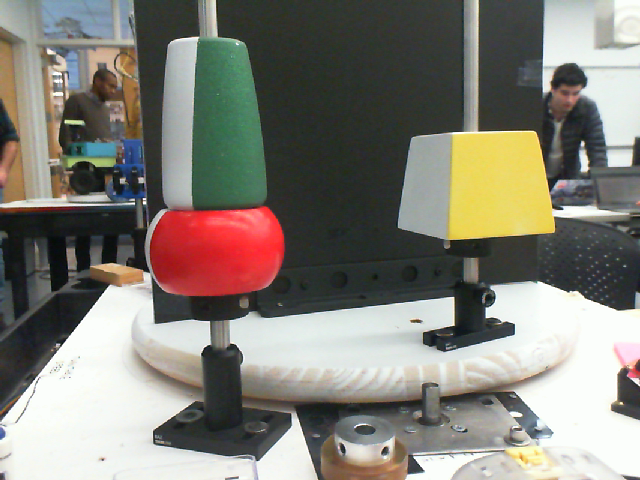

setUpWebcam(roboCam);

% Test camera, wait for user confirm
preview(roboCam);
gCamTest = input( ...
    "Prepare filter, when ready hit enter.","s" ...
    );
clc;
closePreview(roboCam);

% Test IMTool, wait for user confirm
img = snapshot(roboCam);
imtool(img);
gCamTest = input( ...
    "Experiment with IMTool, then hit enter when ready","s" ...
    );
clc;

% Create free floating figure for livescript update help
camWindow = figure( ...
    "name","Robot USB Camera","NumberTitle","off","Visible","on" ...
    );
figure(camWindow)
imshow(img,"Border","tight")


% Configure loop to test n data points
nTest = input("enter small number of camera tests, amd hit enter when ready");
clc;
r= rateControl(0.1);
reset(r);

### Run Control Loop

controlFlag = 1;

while (controlFlag < nTest +1)
    robotIMG = SENSE(roboCam);
    figure(camWindow);
    image(robotIMG);

    THINK();
    ACT();

    camtest = input("move object to new position and hit enter","s");
    clc;

    waitfor(r);
    controlFlag = controlFlag + 1;
end

### Mission data processing

### Clean and Shutdown

End program by...

### Assorted Functions 

### Act Functions

function ACT()
end

### Sense Functions

function setUpWebcam(roboCam)
% Sense function to set up roboCam balance mode and exposure
% Input: roboCam is webcam object to be set up

    boolExpose = input("Would you like to use manual exposure (y/n)?","s");
    if boolExpose == "y"
        roboCam.ExposureMode  = "manual";
        roboCam.Exposure = -8;
    end
    roboCam.WhiteBalanceMode = "manual";
    roboCam.Brightness = 100;

end

function [robotImage] = SENSE(roboCam)
    robotImage = snapshot(roboCam);

end

### Think Functions

function THINK()
end